load hw1dat

% Metal objects: H1
% Wooden objects: H0
hw1dat

hw1dat =    -0.6897    1.1527    1.0000   -0.6995
   -1.0474   -1.1271    1.0000    2.0342
   -1.4434   -0.1100         0   -0.3879
    0.3972    0.9310         0   -0.2666
   -0.0728    2.9866         0   -0.4665
    0.3164    0.3977    1.0000    1.3897
    0.3761    0.9773    1.0000   -0.4119
   -0.2069    1.6059         0   -0.5339
   -1.1938   -1.6905    1.0000    0.9834
   -1.4526   -0.5427    1.0000   -4.1758


% Col 1: data from H0
% Col 2: data from H1
% Col 3: source info for test data
% Col 4: test data
H_0 = hw1dat(:, 1);
H_1 = hw1dat(:, 2);
S_info = hw1dat(:, 3);
test = hw1dat(:, 4);

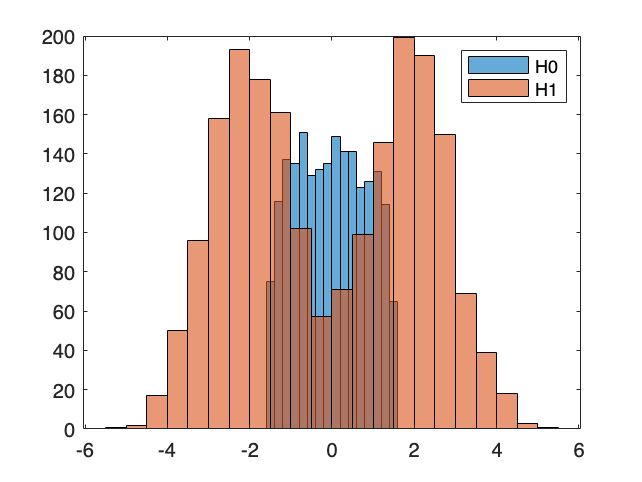

% here I will plot data and I'll try to find a good decision rule.
histogram(H_0, 'DisplayName', 'H0')
hold on
histogram(H_1, 'DisplayName', 'H1')
legend
hold off

[minH1, maxH1] = min(H_1), max(H_1)

minH1 = -5.1042

maxH1 = 864

ans = 5.0624

[minH1, maxHz1] = min(H_0), max(H_0)

minH1 = -1.4959

maxHz1 = 1262

ans = 1.4956


% As we can see, the range for H0 is (-1.5 , 1.5) and no data point is out
% of this range. But for H1 we don't have a constraining range, instead we
% have two peaks at -2 and 2. 

% Now for choosing decision rule: 
% To begin with, I choose the easiest option, if Y was in (-1.5, 1.5) we
% choose H0.
% This may not be a good choice of decision rule but it's the first that
% came to my mind. Now for computing P_j(Gamma_i):
% P_1_gamma_1 = # of H_1 outside (-1.5, 1.5) / # total in H_1
% P_0_gamma_1 = # of H_0 outside (-1.5, 1.5) / # total in H_0 = 0
% P_1_gamma_0 = # of H_1 inside (-1.5, 1.5) / # total in H_1
% P_0_gamma_0 = # of H_0 inside (-1.5, 1.5) / # total in H_0 = 1
H_1_inside_first = sum(H_1 > -1.5 & H_1 < 1.5)

H_1_inside_first = 636

H_1_outside_first = sum(H_1 <= -1.5 | H_1 >= 1.5)

H_1_outside_first = 1364


P_1_gamma_1_first = H_1_outside_first / 2000

P_1_gamma_1_first = 0.6820

P_0_gamma_1_first = 0

P_0_gamma_1_first = 0

P_1_gamma_0_first = H_1_inside_first / 2000

P_1_gamma_0_first = 0.3180

P_0_gamma_0_first = 1

P_0_gamma_0_first = 1


% Now for the second decision rule, let's shrink the chosen range and see
% what will occur, let's choose (-1, 1):
% P_1_gamma_1 = # of H_1 outside (-1, 1) / # total in H_1
% P_0_gamma_1 = # of H_0 outside (-1, 1) / # total in H_0
% P_1_gamma_0 = # of H_1 inside (-1, 1) / # total in H_1
% P_0_gamma_0 = # of H_0 inside (-1, 1) / # total in H_0
H_1_inside_second = sum(H_1 > -1 & H_1 < 1)

H_1_inside_second = 329

H_1_outside_second = sum(H_1 <= -1 | H_1 >= 1)

H_1_outside_second = 1671

H_0_inside_second = sum(H_0 > -1 & H_0 < 1)

H_0_inside_second = 1362

H_0_outside_second = sum(H_0 <= -1 | H_0 >= 1)

H_0_outside_second = 638



P_1_gamma_1_second = H_1_outside_second / 2000

P_1_gamma_1_second = 0.8355

P_0_gamma_1_second = H_0_outside_second / 2000

P_0_gamma_1_second = 0.3190

P_1_gamma_0_second = H_1_inside_second / 2000

P_1_gamma_0_second = 0.1645

P_0_gamma_0_second = H_0_inside_second / 2000

P_0_gamma_0_second = 0.6810

% Now we try to compute Bayes risk and estimate prior probabilities:
% Ignoring our maxH1, we choose our space to be (-6, 6) since not many data
% points go outside this range.
% Now we estimate our prior probabilities:
P_0_first = 0.5;
P_1_first = 0.5;
P_0_second = 0.333;
P_1_second = 0.666;

% Now for computing r we need to find Rj. I choose costs as C00 = C11 = 0
% and C10 = C01 = 1
R1_first = P_1_gamma_0_first

R1_first = 0.3180

R0_first = P_0_gamma_1_first

R0_first = 0

R1_second = P_1_gamma_0_second

R1_second = 0.1645

R0_second = P_0_gamma_1_second

R0_second = 0.3190


r_first = P_0_first*R0_first + P_1_first*R1_first

r_first = 0.1590

r_second = P_0_second*R0_second + P_1_second*R1_second

r_second = 0.2158